## **Sahan Sulochana Hettiarachchi**

## **180237G**

## **BME**

## **Preliminaries**

# **1. Smoothing filters **

## 1.1. Moving average MA(N) filter

% Loading the ECG_template.mat file
load('ECG_template.mat');
rawData = ECG_template;

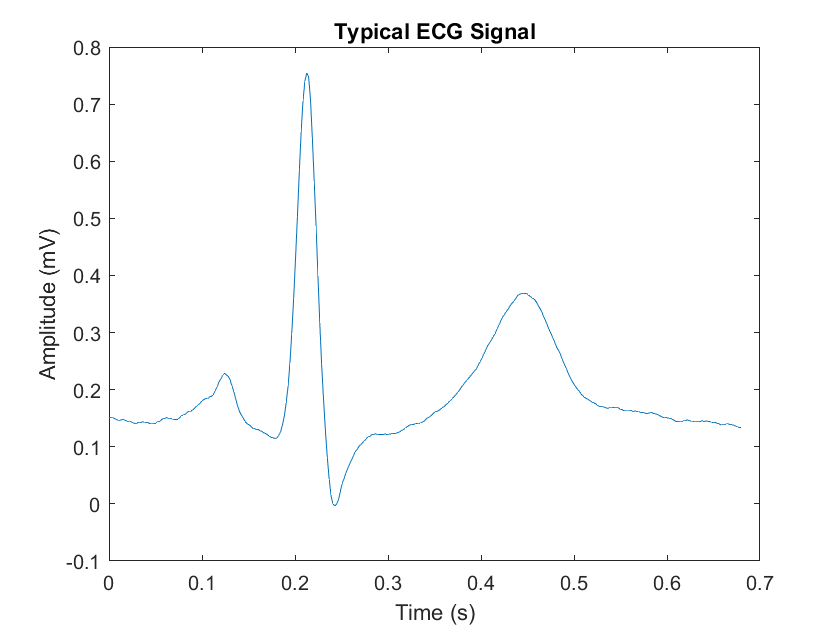

%Plotting the loaded signal
[~,t] = size(rawData);
fs = 500; %Sampling Frequency
T = linspace(0,t/fs,t);
figure('Name','Raw Data');
plot(T,ECG_template);
title('Typical ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (mV)');

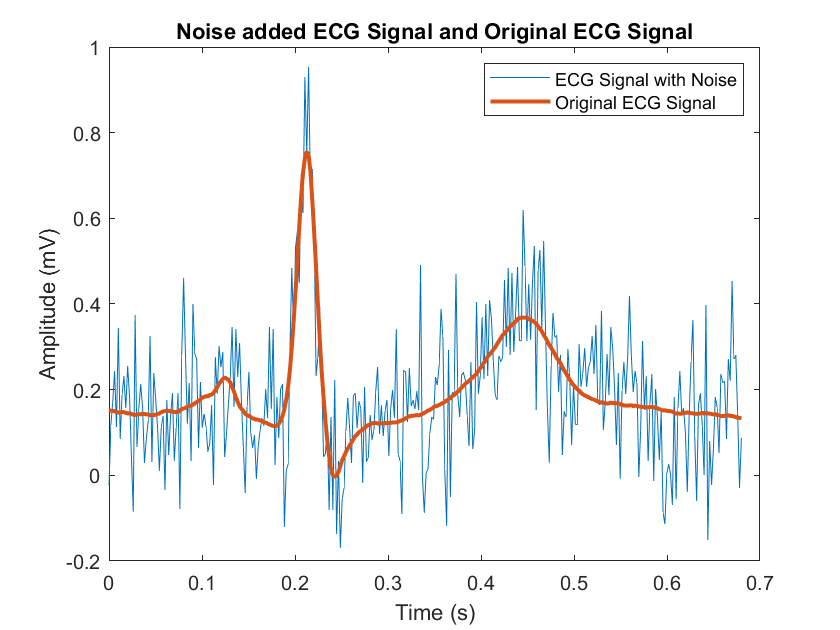

%Adding the White Gaussian noise 5 dB
nECG = awgn(rawData,5,'measured');
figure('Name','Noise added ECG');
p=plot(T,nECG,T,ECG_template);
p(2).LineWidth = 2;
title('Noise added ECG Signal and Original ECG Signal');
legend('ECG Signal with Noise','Original ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (mV)');

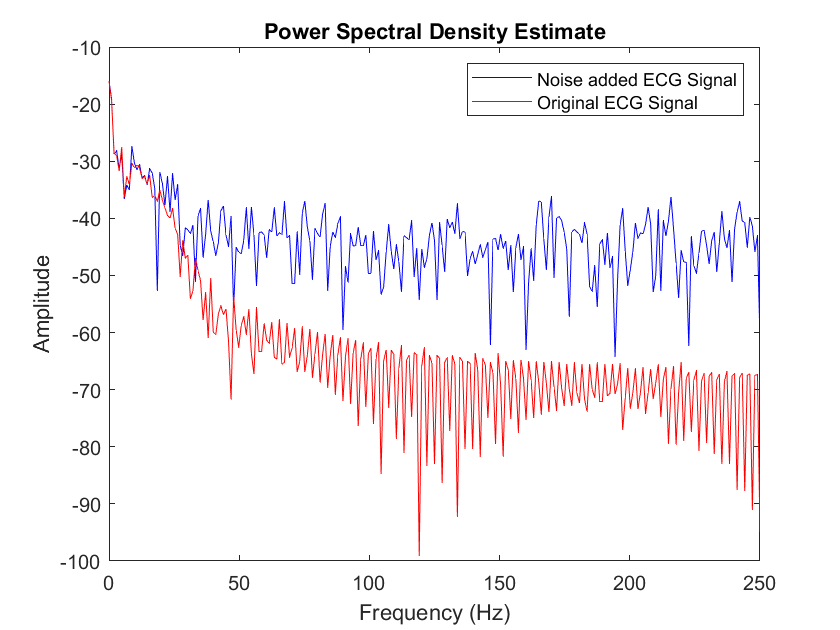

%Plotting Power Spectral Density
%Default window - Rectangular window 
figure('Name', 'PSD');
[n_psd,n_w] = periodogram(nECG,[],2^nextpow2(length(nECG)),fs); 
[psd,w] = periodogram(ECG_template,[],2^nextpow2(length(ECG_template)),fs);
plot(n_w,10*log10(n_psd) , 'b',w,10*log10(psd) , 'r' );

title('Power Spectral Density Estimate')
legend('Noise added ECG Signal','Original ECG Signal');
xlabel('Frequency (Hz)')
ylabel('Amplitude')

**MA(3) filter implementation with a customised script**

order = 3;
[~,nx] = size(nECG);
ma3ECG_1 = zeros(1,nx);

% y[0] = (1/3) x[0]
% y[1] = (1/3) (x[0] + x[1])
% y[2] = (1/3) (x[0] + x[1] + x[2])
% y[3] = (1/3) (x[1] + x[2] + x[3])

for n = 1:nx
        ma3ECG_1(n) = (sum(nECG(max([1,n-order+1]):n)))/(order+1);
    end

%Deriving the Group delay (Filter Order-1/2)
 groupDelay = (order-1)/2;

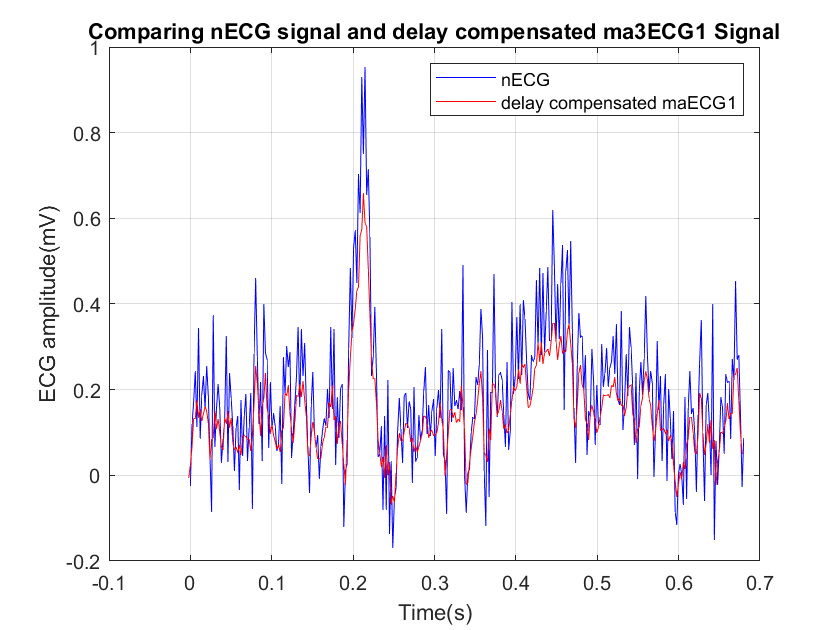

% Plotting the delay compensated ma3ECG_1 and nECG
dcT = T-(groupDelay/fs);
figure('Name', 'MA(3)');
plot(T,nECG,'b',dcT,ma3ECG_1,'r');
title('Comparing nECG signal and delay compensated ma3ECG{1} Signal')
legend('nECG', 'delay compensated maECG{1}');
xlabel('Time(s)'), ylabel('ECG amplitude(mV)');
grid on

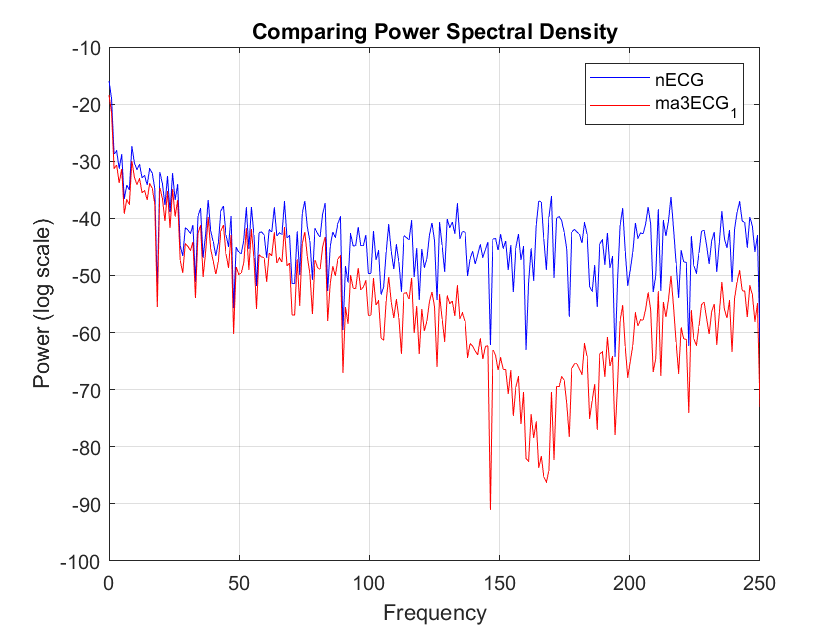

% Producing the PSD of ma3ECG and nECG
window = rectwin(t);
[psd1,w1] = periodogram(nECG,window,512,fs);
[psd2,w2] = periodogram (ma3ECG_1,window,512,fs);
figure('Name','Overlapping PSDs of ma3ECG_1 and nECG');
plot(w1,10*log10(psd1),'b',w2,10*log10(psd2),'r')
title('Comparing Power Spectral Density')
legend('nECG','ma3ECG_1');
xlabel('Frequency')
ylabel('Power (log scale)')
grid on

**MA(3) filter implementation with the MATLAB built-in function **

%Generating filtered signal ma3ECG_2
b = (1/order) * ones(1,order); %order = 3 
a = 1;
ma3ECG_2 = filter(b,a,nECG);
%same group delay as the filter order is same

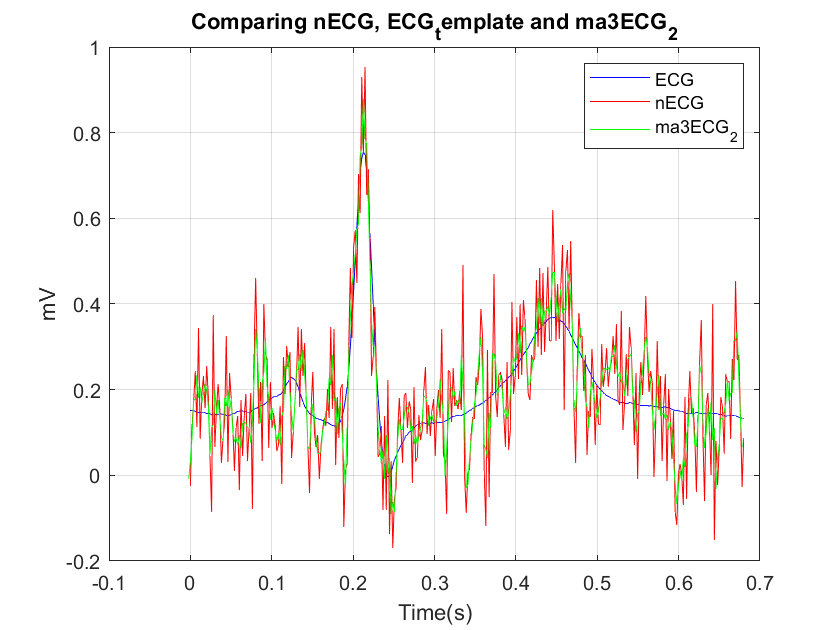

% Plotting nECG, ECG_template and ma3ECG_2 on the same plot and compare
figure('Name','Comparing ECG, nECG and ma3ECG_2');
plot(T,rawData,'b',T,nECG,'r',dcT,ma3ECG_2,'g');
title('Comparing nECG, ECG_template and ma3ECG_2');
legend('ECG', 'nECG','ma3ECG_2');
xlabel('Time(s)');
ylabel('mV');
grid on

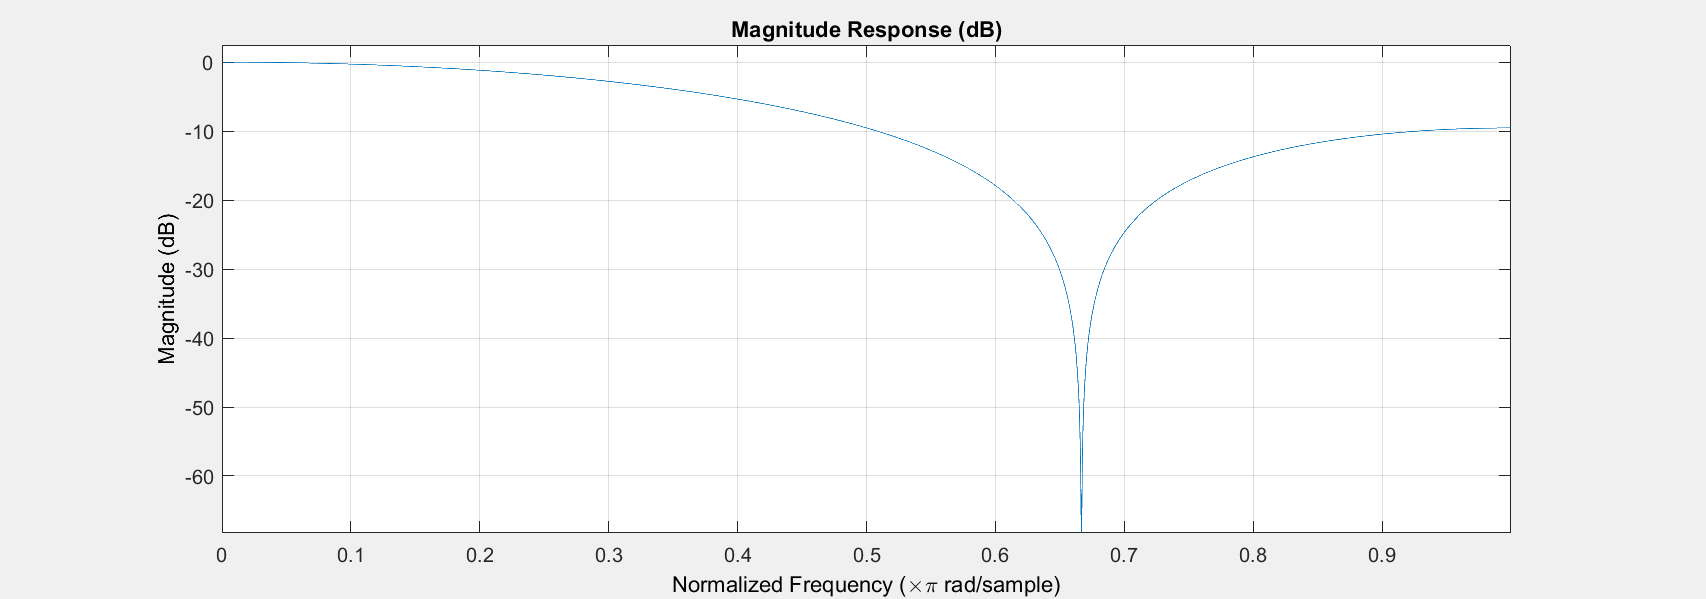

%Use fvtool to inspect the magnitude response, phase response and pole-zero plot
fvtool(b,a);

**1.1.1       MA(10) filter implementation with the MATLAB built-in function**

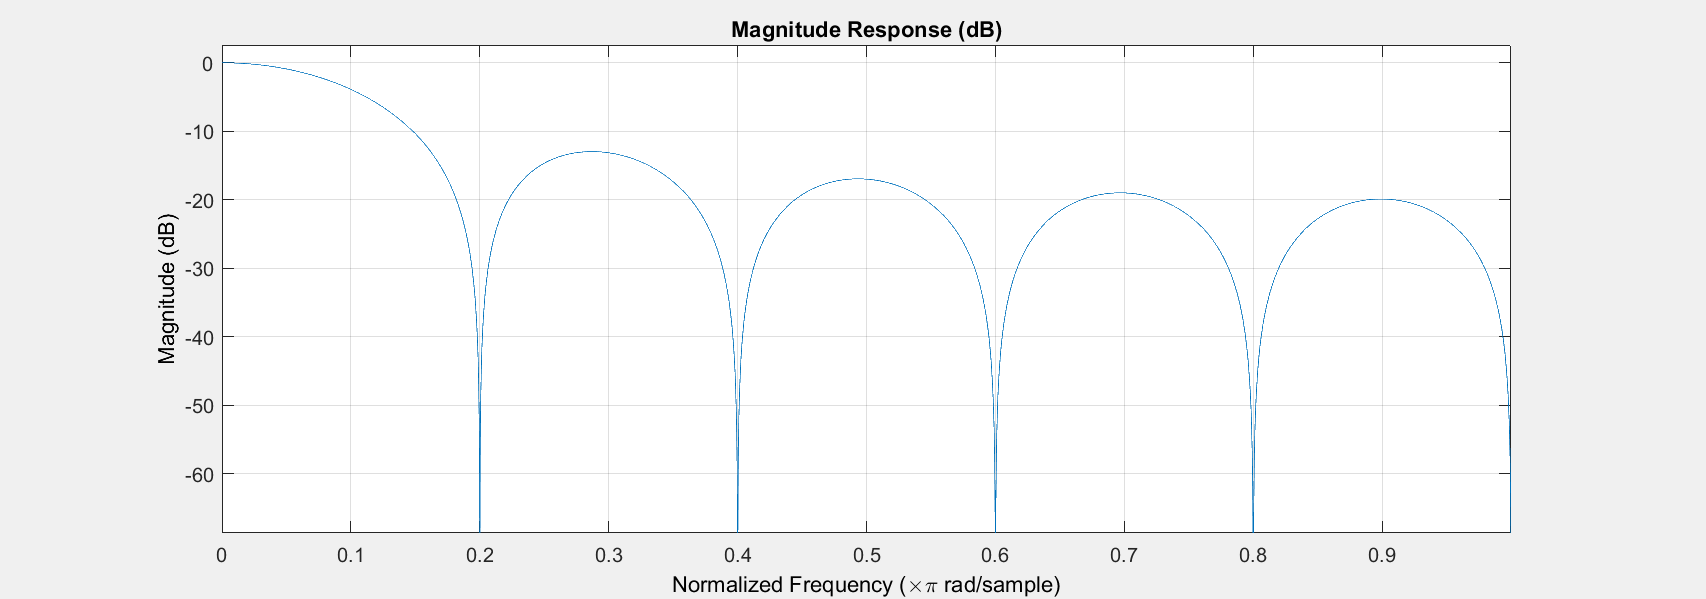

%Identifing the improvement of the MA(10) filter over the MA(3) filter
newOrder = 10;
b10 = (1/newOrder) * ones(1,newOrder);
a10 = 1;
fvtool(b10,a10);

%Filtering nECG using MA(10) filter compensating for group delay
ma10ECG = filter(b10,a10,nECG);
groupDelay10 = (newOrder-1)/2;
dcT10 = T-round(groupDelay10)/fs;

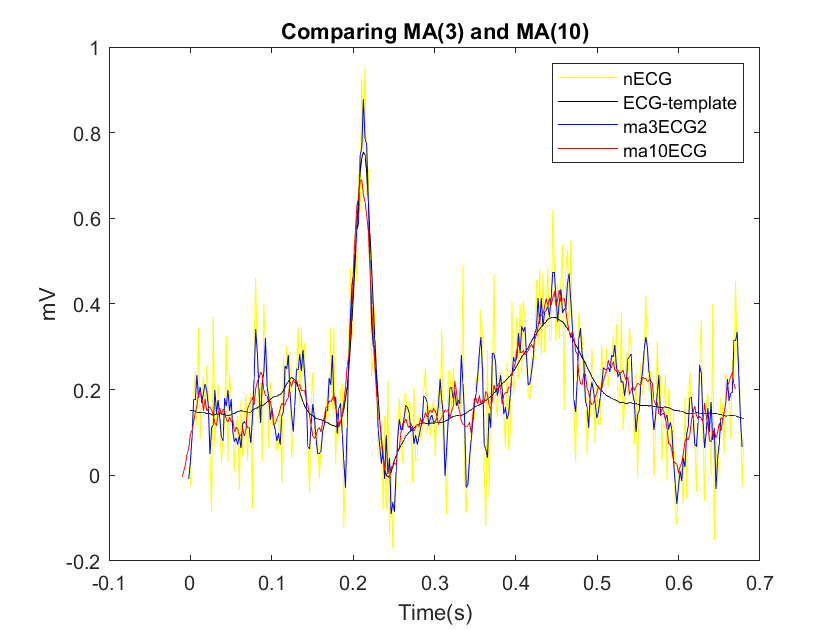

%Ploting nECG, ECG_template, ma3ECG_2 and ma10ECG on the same plot
figure('Name','Comparing MA(3) and MA(10)');
plot(T,nECG,'y',T,rawData,'k',dcT,ma3ECG_2,'b',dcT10,ma10ECG,'r');
title('Comparing MA(3) and MA(10)');
legend ('nECG', 'ECG-{template}','ma3ECG2','ma10ECG')
xlabel('Time(s)')
ylabel('mV')

**Optimum MA(N) filter order**

iteration = 100;
error = zeros(1,iteration);
for n= 1:iteration

    bn = (1/n)*ones(1,n);
    an = 1;
    maNECG = filter(bn,an,nECG);

    groupDelayN = (n-1)/2;

    %compensating the signal to calculate the MSE
    maNECG(1 : length(maNECG)- round(groupDelayN)) = maNECG(round(groupDelayN) + 1  : end);
    maNECG(length(maNECG)- round(groupDelayN) + 1: end)=0;

    diff = (rawData-maNECG);
    error(n)= (diff*diff')/length(rawData);


end

[optimum_value,optimum] = min(error);

%Required for the next parts
opt_b = (1/optimum) * ones(1,optimum);
opt_a =  1;
maoptECG = filter(opt_b,opt_a,nECG);
group_delay = (optimum-1)/2;
dcTopt = T-round(group_delay)/fs;

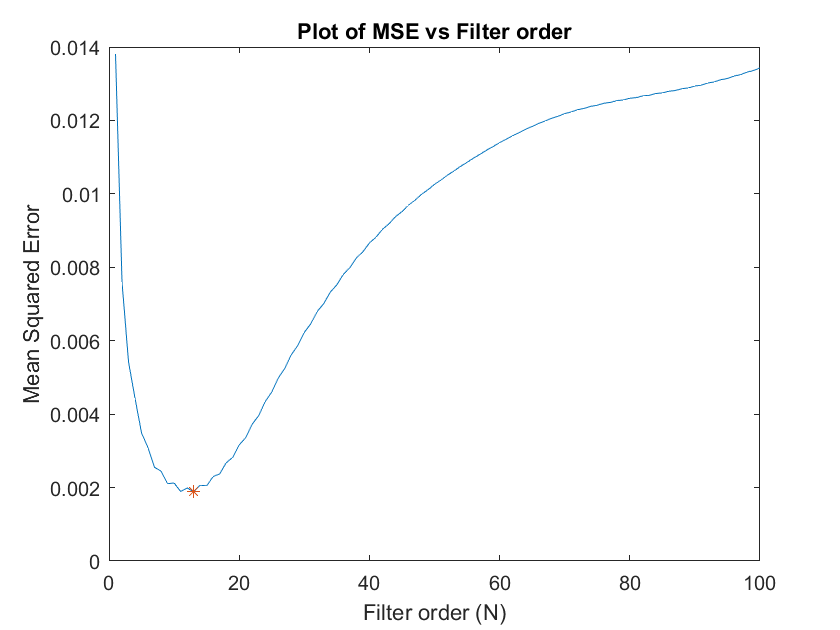

figure('Name','Plot of MSE vs Filter order');
plot(linspace(1,iteration,iteration),error, optimum, optimum_value, '*');
title('Plot of MSE vs Filter order');
xlabel('Filter order (N)');
ylabel('Mean Squared Error');

## **1.2. Savitzky-Golay SG(N,L) filter**

%Applying Saviztsky Golay Filters SG(3,11)
sg310ECG = sgolayfilt(nECG,3,(2*11+1));
figure('Name','Applying Saviztsky Golay Filters SG(3,11)');

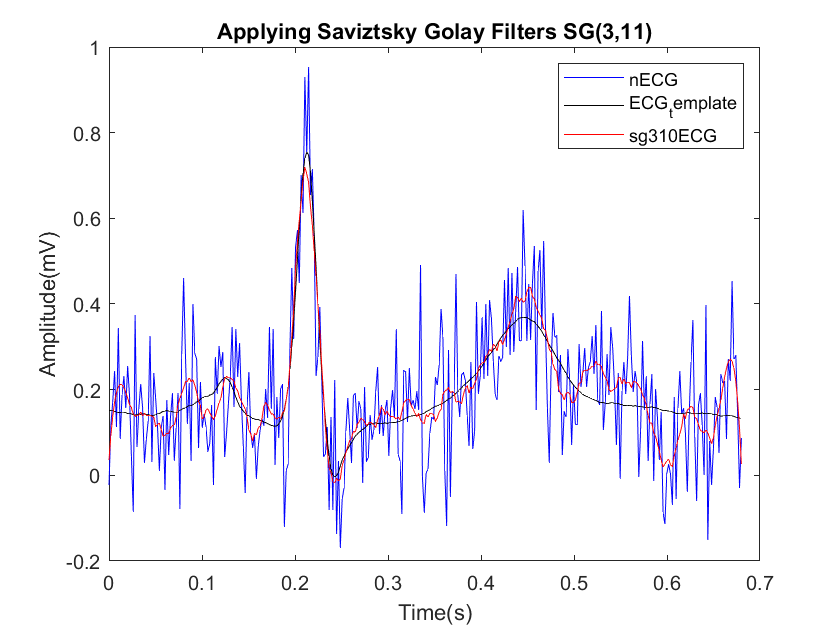

%Plotting the nECG, rawData and sg310ECG
plot(T,nECG,'b',T,rawData,'k',T,sg310ECG,'r');
legend ('nECG', 'ECG_template','sg310ECG')
title('Applying Saviztsky Golay Filters SG(3,11)')
xlabel('Time(s)')
ylabel('Amplitude(mV)')

**Optimum SG(N,L) filter parameter**

length = 150; %Length
nOrder = min([(2*length),30]); %order of the Polynomial
err = NaN([length,nOrder]);
for l = 1:length
    n_max = min([(2*l),nOrder]);
    for n = 1:n_max
        err(l,n) =immse(sgolayfilt(nECG,n,(2*l+1)),rawData);
    end
end

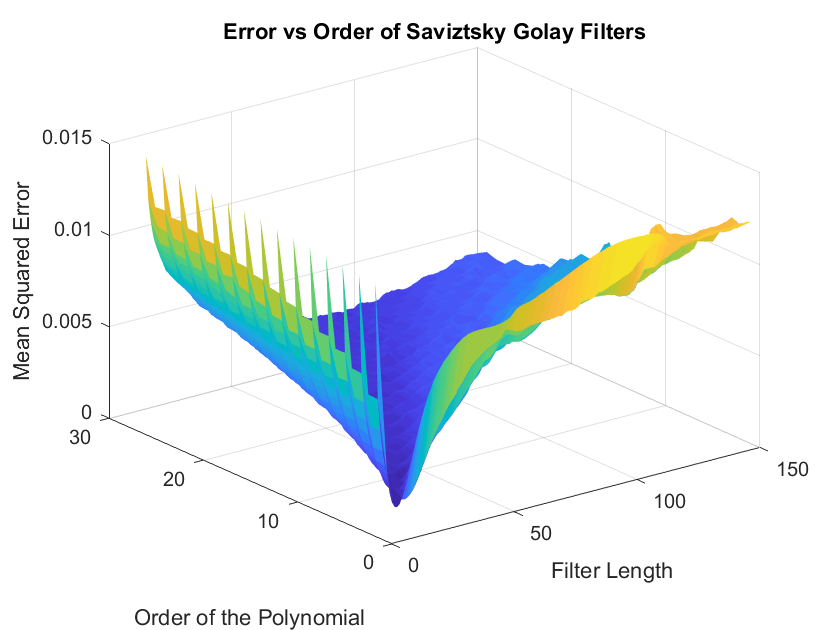

X = linspace(1,length,length);
Y = linspace(1,nOrder,nOrder);
figure('Name','Error vs Order of Saviztsky Golay Filters');
surf(X,Y,err');

shading flat
title('Error vs Order of Saviztsky Golay Filters')
xlabel('Filter Length')
ylabel('Order of the Polynomial')
zlabel('Mean Squared Error')

[v, ind] = min(err); % returns min value of each column
[~, optind] = min(v); % returns min value of the min value column

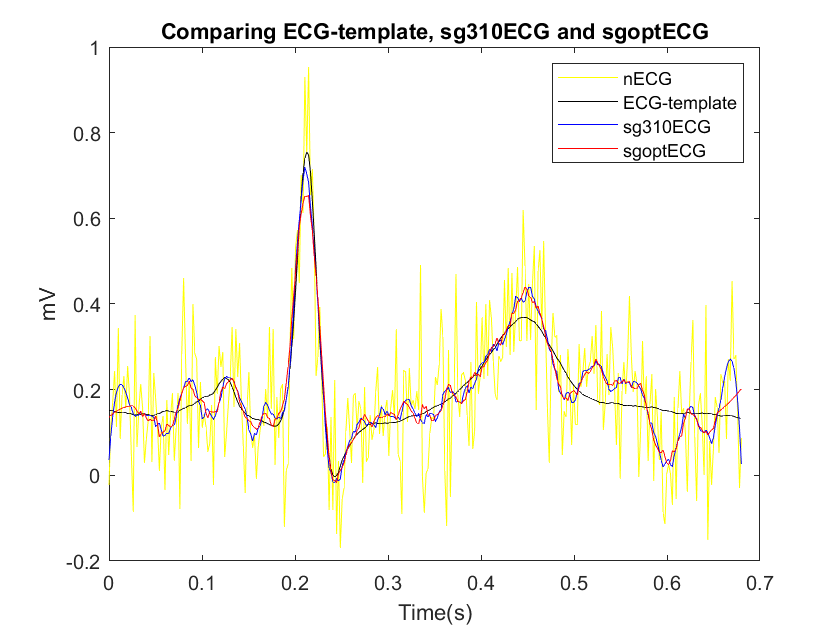

sgoptECG = sgolayfilt(nECG,optind,2*ind(optind)+1); 
figure('Name','Comparing ECG_template, sg310ECG and sgoptECG');
plot(T,nECG,'y',T,rawData,'k',T,sg310ECG,'b',T,sgoptECG,'r');
title('Comparing ECG-template, sg310ECG and sgoptECG');
legend ('nECG', 'ECG-template','sg310ECG','sgoptECG')
xlabel('Time(s)')
ylabel('mV')

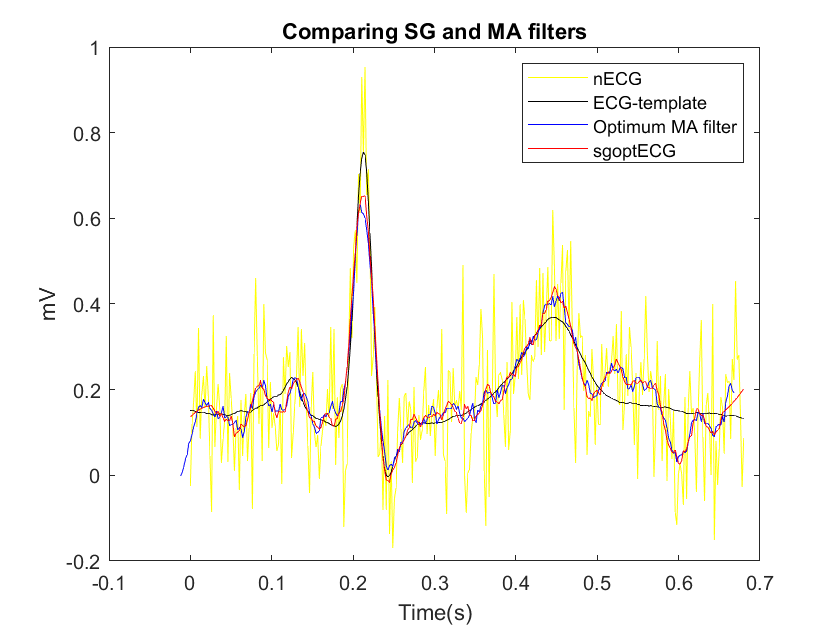

%Comparing SG and AM filters
figure('Name','Comparing SG and MA filters');
plot(T,nECG,'y',T,rawData,'k',dcTopt,maoptECG,'b',T,sgoptECG,'r');
title('Comparing SG and MA filters');
legend ('nECG', 'ECG-template','Optimum MA filter','sgoptECG')
xlabel('Time(s)')
ylabel('mV')